% Import data
X_train = table2array(readtable("X_train.csv"))
Y_train = table2array(readtable("Y_train.csv"))
X_test = table2array(readtable("X_test.csv"))
Y_test = table2array(readtable("Y_test.csv"))
X_train = X_train(2:138213,2:8)
X_test = X_test(2:34554,2:8)
Y_train = Y_train(2:138213,2)
Y_test = Y_test(2:34554,2)

% Try and fit a model
model = fitlm(X_train,Y_train)

## Make graphics

my_x = readtable("master_table_filtered.csv")

my_x = 172765×12 table
    Var1    DepartmentId    OrderDate    OrderItemQuantity    DaysForShipping_real_    DaysForShipment_scheduled_    LateDelivery    OrderStatus    Market    OrderRegion    CustomerSegment    DeliveryStatus
    ____    ____________    _________    _________________    _____________________    __________________________    ____________    ___________    ______    ___________    _______________    ______________

      0          2              3                1                      3                          4                      0               1           3   

x = my_x

x = 172765×12 table
    Var1    DepartmentId    OrderDate    OrderItemQuantity    DaysForShipping_real_    DaysForShipment_scheduled_    LateDelivery    OrderStatus    Market    OrderRegion    CustomerSegment    DeliveryStatus
    ____    ____________    _________    _________________    _____________________    __________________________    ____________    ___________    ______    ___________    _______________    ______________

      0          2              3                1                      3                          4                      0               1           3      

dep = table2array(x(:,2));
market = table2array((x(:,9)));
quantity = table2array((x(:,4)));
status = table2array((x(:,12)));
scheduled= table2array((x(:,6)));
customer = table2array((x(:,11)));
y = table2array(my_x(:,7));


Make boxplots and scatterplots

##Department ID?

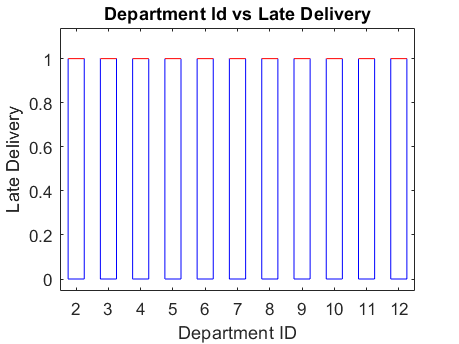

boxplot(y,dep)
xlabel("Department ID")
ylabel("Late Delivery")
title("Department Id vs Late Delivery")

corrcoef(dep,y)

ans =     1.0000    0.0007
    0.0007    1.0000


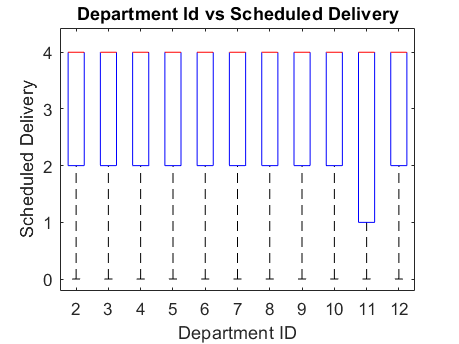

boxplot(scheduled,dep)
xlabel("Department ID")
ylabel("Scheduled Delivery")
title("Department Id vs Scheduled Delivery")

corrcoef(dep,y)

ans =     1.0000    0.0007
    0.0007    1.0000


Market

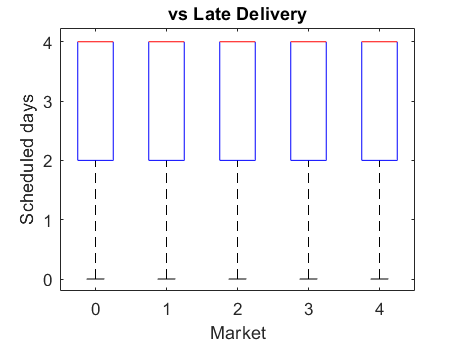

boxplot(scheduled,market)
xlabel("Market")
ylabel("Scheduled days")
title("vs Late Delivery")

corrcoef(market,scheduled)

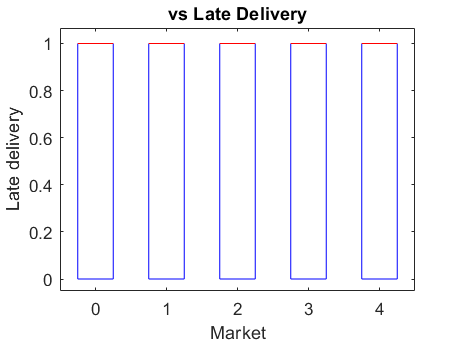

boxplot(y,market)
xlabel("Market")
ylabel("Late delivery")
title("vs Late Delivery")

corrcoef(market,y)

ans =     1.0000    0.0000
    0.0000    1.0000


Customer segment

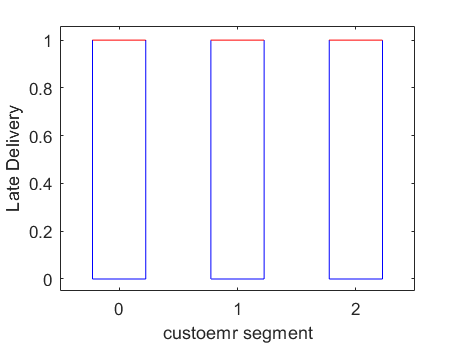

boxplot(y,customer)
xlabel("custoemr segment")
ylabel("Late Delivery")

corrcoef(customer,y)

ans =     1.0000    0.0011
    0.0011    1.0000


Scheduled

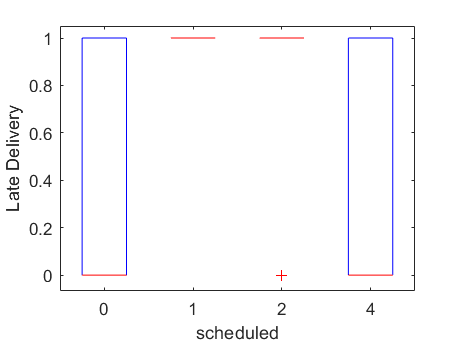

boxplot(y,scheduled)
xlabel("scheduled")
ylabel("Late Delivery")

ans =     1.0000   -0.3896
   -0.3896    1.0000


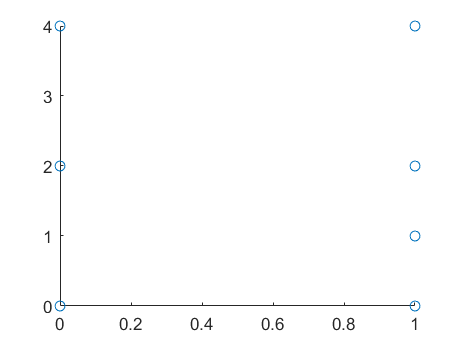

corrcoef(scheduled,y)